# **Dylan Thornburg ECEN 133 Prelab 7:** 

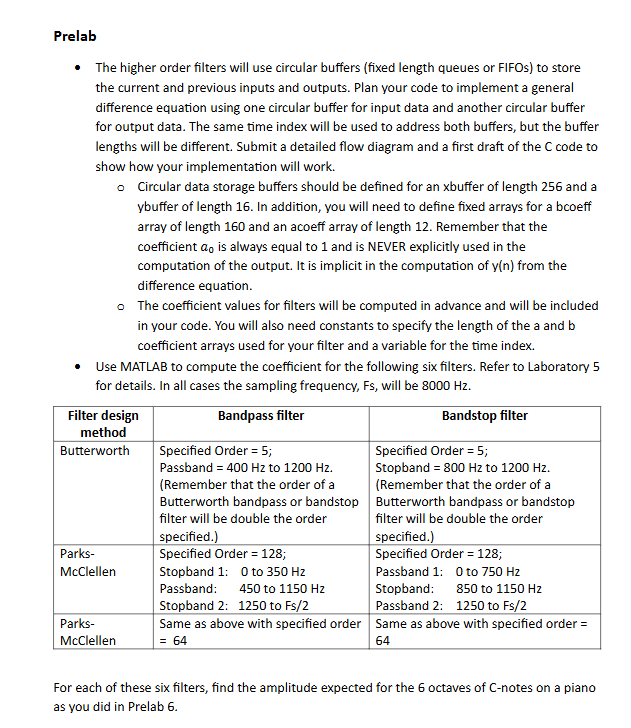

General IIR Filter Formula:

**FLOWCHART:**

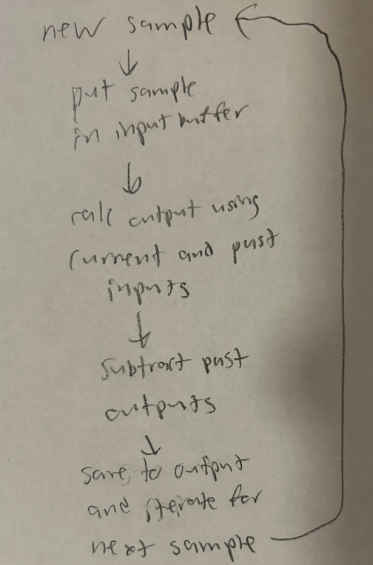

**C CODE **

**MATLAB CODE**

Fs = 8000;                        
f = linspace(0, Fs/2, 1024);      

% C8 to C3
C_freqs = [4186.01, 2093, 1046.5, 523.25, 261.63, 130.81];
C_labels = {'C8','C7','C6','C5','C4','C3'};

%Butterworth Bandpass
[b,a] = butter(5, [400 1200]/(Fs/2), 'bandpass');
[H, fvec] = freqz(b, a, 1024, Fs);
for i = 1:length(C_freqs)
    [~, index] = min(abs(fvec - C_freqs(i)));
    fprintf('%s: %.4f\n', C_labels{i}, abs(H(index)));
end

C8: 0.0000
C7: 0.0053
C6: 0.9831
C5: 0.9994
C4: 0.0369
C3: 0.0006


%Butterworth Bandstop 
[b,a] = butter(5, [800 1200]/(Fs/2), 'stop');
[H, fvec] = freqz(b, a, 1024, Fs);
for i = 1:length(C_freqs)
    [~, index] = min(abs(fvec - C_freqs(i)));
    fprintf('%s: %.4f\n', C_labels{i}, abs(H(index)));
end

C8: 1.0000
C7: 1.0000
C6: 0.0026
C5: 1.0000
C4: 1.0000
C3: 1.0000


%Parks-McClellan Bandpass Order 128
fpm = [0 350 450 1150 1250 Fs/2]/(Fs/2);
apm = [0 0 1 1 0 0];
b = firpm(128, fpm, apm);
a = 1;
[H, fvec] = freqz(b, a, 1024, Fs);
for i = 1:length(C_freqs)
    [~, index] = min(abs(fvec - C_freqs(i)));
    fprintf('%s: %.4f\n', C_labels{i}, abs(H(index)));
end

C8: 0.0206
C7: 0.0026
C6: 0.9990
C5: 0.9791
C4: 0.0132
C3: 0.0110


%Parks-McClellan Bandstop Order 128
fpm = [0 750 850 1150 1250 Fs/2]/(Fs/2);
apm = [1 1 0 0 1 1];
b = firpm(128, fpm, apm);
a = 1;
[H, fvec] = freqz(b, a, 1024, Fs);
for i = 1:length(C_freqs)
    [~, index] = min(abs(fvec - C_freqs(i)));
    fprintf('%s: %.4f\n', C_labels{i}, abs(H(index)));
end

C8: 0.9777
C7: 0.9999
C6: 0.0106
C5: 1.0074
C4: 1.0190
C3: 1.0226


%Parks-McClellan Bandpass Order 64
fpm = [0 350 450 1150 1250 Fs/2]/(Fs/2);
apm = [0 0 1 1 0 0];
b = firpm(64, fpm, apm);
a = 1;
[H, fvec] = freqz(b, a, 1024, Fs);
for i = 1:length(C_freqs)
    [~, index] = min(abs(fvec - C_freqs(i)));
    fprintf('%s: %.4f\n', C_labels{i}, abs(H(index)));
end

C8: 0.1087
C7: 0.1086
C6: 1.0742
C5: 1.1078
C4: 0.0950
C3: 0.0997


%Parks-McClellan Bandstop Order 64
fpm = [0 750 850 1150 1250 Fs/2]/(Fs/2);
apm = [1 1 0 0 1 1];
b = firpm(64, fpm, apm);
a = 1;
[H, fvec] = freqz(b, a, 1024, Fs);
for i = 1:length(C_freqs)
    [~, index] = min(abs(fvec - C_freqs(i)));
    fprintf('%s: %.4f\n', C_labels{i}, abs(H(index)));
end

C8: 1.0798
C7: 0.9503
C6: 0.0110
C5: 1.0237
C4: 1.0469
C3: 0.9633
